# Определение нот

Начало программы

Очистка Workspace

clear all
close all

Определяю таблицу частот и нот

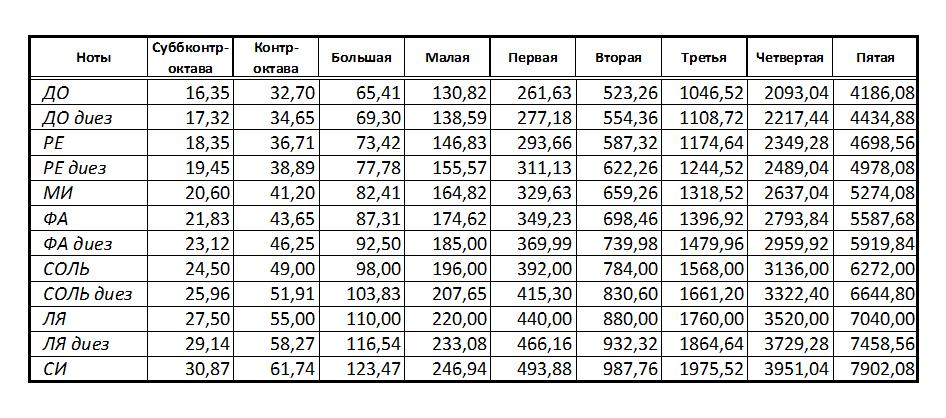

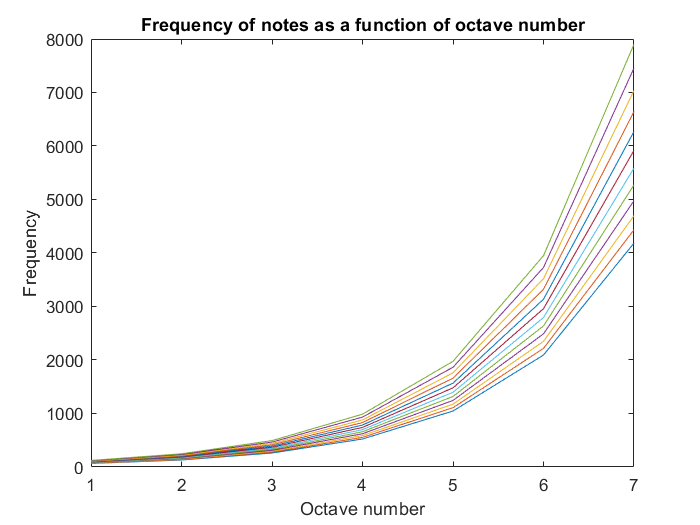

% Большая октава
Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];

% Математически получаем частоты остальных октав
k = 2.^(0:6);
Tab_F = k' .* repmat(Tab_F_1, 7, 1);

figure (1)
plot(Tab_F)
xlabel("Octave number")
ylabel("Frequency")
title("Frequency of notes as a function of octave number")

Очистка от ненужного

clear Tab_F_1  k

Определяю матрицу сумм, в которую из спектра я буду складывать составляющие по частотам каждой ноты. КАждая ячейка соответствует мощности в спектре конкретной ноты конкретной октавы.

M = zeros(7, 12);

Загрузка аудиофайла с 60 нотами подряд

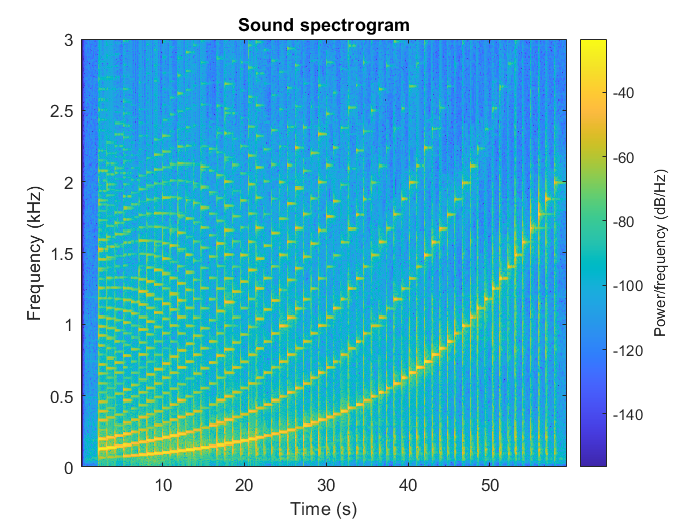

path = 'D:\Desktop\Studie\Diploma\Audio data\wav\60 нот.wav';
[y, Fs] = audioread(path);

z = y(:,1);
figure (1)
spectrogram(z,6000, 2000,6000,Fs,'yaxis')
title('Sound spectrogram')
ylim([0 3])

Очистка от ненужного

clear y path

Определяю максимальную пачку отчетов спектр которого я могу брать для анализа, что бы заметить самую быструю ноту.

bpm = 120;          % 120 таков в минуту
bps = bpm/60;       % или 2 доли в секунду
t_d = 1/bps;        % что есть 0.5сек на долю
Note_min = 1/16;    % Условно минимальная продолжительность ноты
                    % 1/16 доли

T_min = Note_min * t_d

T_min = 0.0313


Fs = 44100;         % При частоте дискретизации 44 100Гц получаем
Samples_num = T_min * Fs

Samples_num = 1.3781e+03


Samples_num = 1024  % С округлением в низ

Samples_num = 1024


df = Fs/Samples_num % В таком случае шаг частоты спектра 43Гц

df = 43.0664

Очистка от ненужного

clear bpm bps t_d Note_min T_min df

Определение векторов "Vi" для извлечения амплитуд. АЛЬТЕРНАТИВА: находим массив "Indexes" индексов которые соответствуют нотам 

Для начала выделю участок сигнала и проинтерполирую его спектр

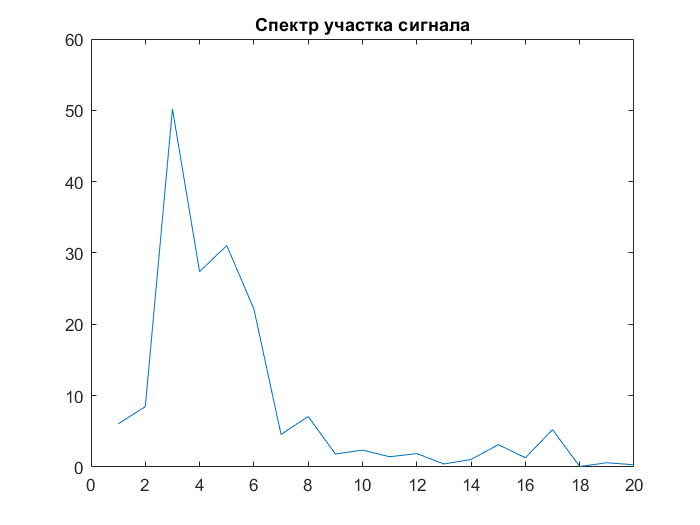

Fs = 44100;
i = 400;
S = z(i*Samples_num: (i+1)*Samples_num -1);

L = length(S);
df = Fs/L;

figure(1)
plot(abs(fft(S)))
xlim([0 20])
title("Спектр участка сигнала")

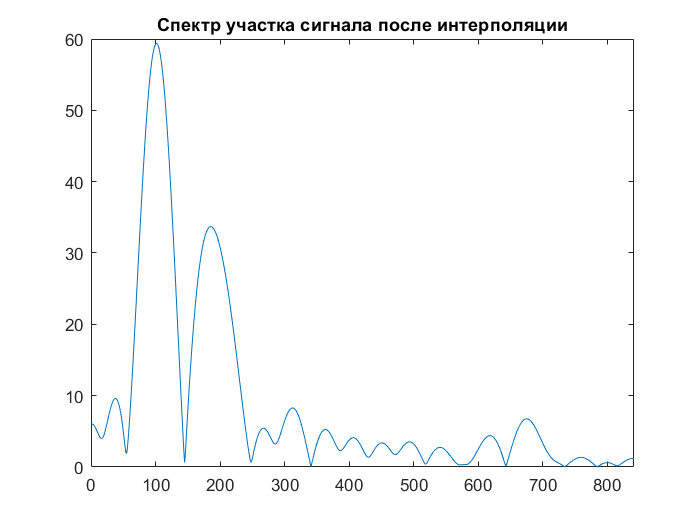


k_interp = Fs/length(S) - 1;
zeros_num = floor( k_interp*Samples_num );
Zer = zeros(zeros_num, 1);
S2 = vertcat (Zer, S);

L2 = length(S2);
df2 = Fs/L2;

figure(2)
plot(abs(fft(S2)))
xlim([0 20] * k_interp)
title("Спектр участка сигнала после интерполяции")

Теперь, имея удобный спектр, найду индексы, которые соответствуют частотам нот

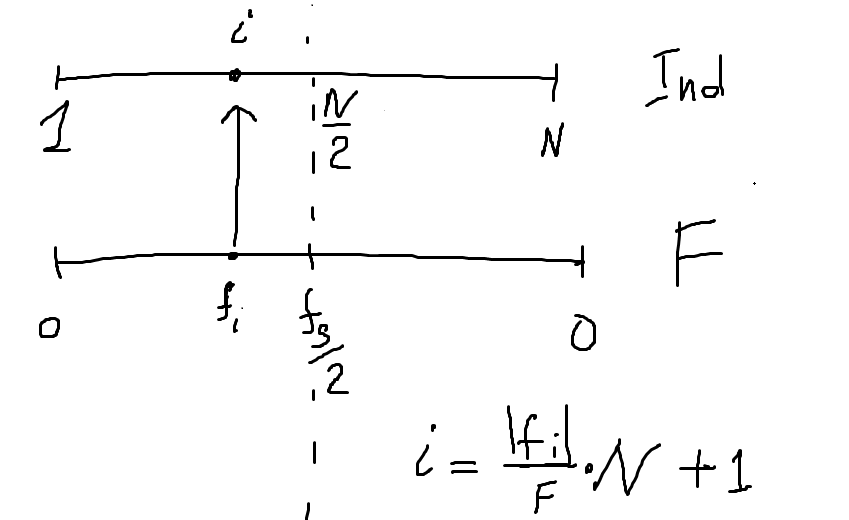

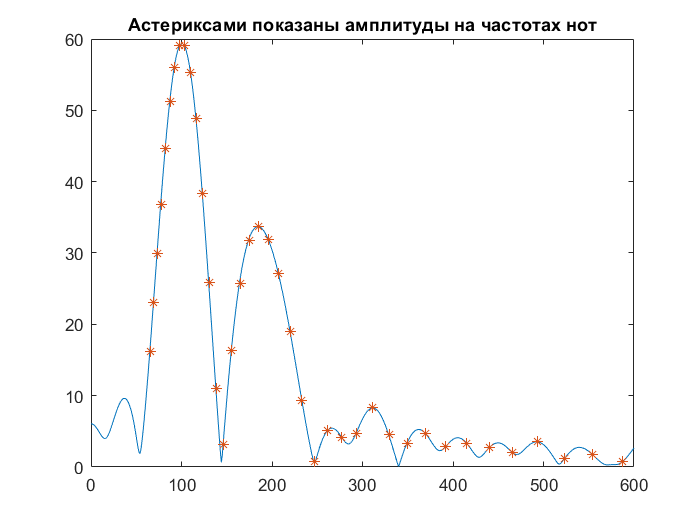

FlatTab_F = reshape(Tab_F.',1,[]);               % FLAT!!!
Indexes = floor(L2 * FlatTab_F / Fs + 1);


Spec = abs(fft(S2));
Spec = Spec(1:L2/2);
f = 0:df2:Fs/2-df2;


figure (3)
plot(f, Spec, FlatTab_F, Spec(Indexes), '*')
xlim([0 600])
title("Астериксами показаны амплитуды на частотах нот")

Проба записи матрицы М для 1го слайса

# ИЗМЕНЯЙ "i" И НАБЛЮДАЙ 3Д ИЗОБРАЖЕНИЕ МАТРИЦЫ

i = 1...2500

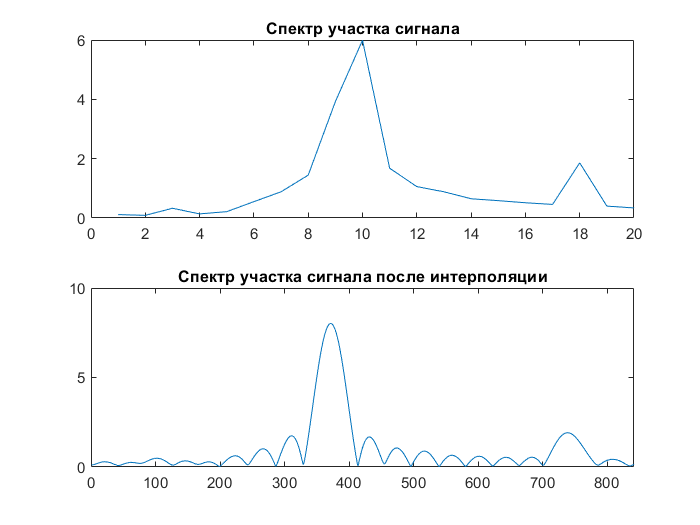

i = 1350;
S = z(i*Samples_num: (i+1)*Samples_num - 1);

figure(1)
subplot(2,1,1)
plot(abs(fft(S)))
xlim([0 20])
title("Спектр участка сигнала")

k_interp = Fs/length(S) - 1;
zeros_num = floor( k_interp*Samples_num );
Zer = zeros(zeros_num, 1);
S2 = vertcat (Zer, S);

figure(1)
subplot(2,1,2)
plot(abs(fft(S2)))
xlim([0 20] * k_interp)
title("Спектр участка сигнала после интерполяции")

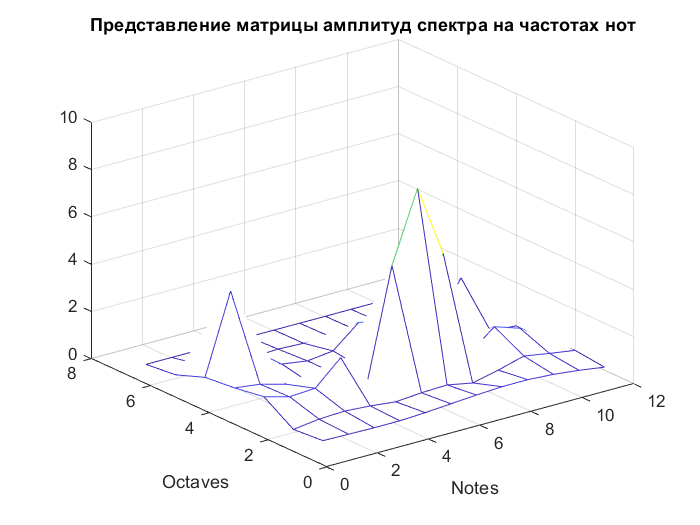



Indexes = floor(L2 * Tab_F / Fs + 1);   % NOT FLAT!!!


Spec = abs(fft(S2));
Spec = Spec(1:L2/2);

M = Spec(Indexes);

figure(2)
mesh(M);
xlabel("Notes")
ylabel("Octaves")
title("Представление матрицы амплитуд спектра на частотах нот")

Определение 1 ноты определением максимума матрицы М

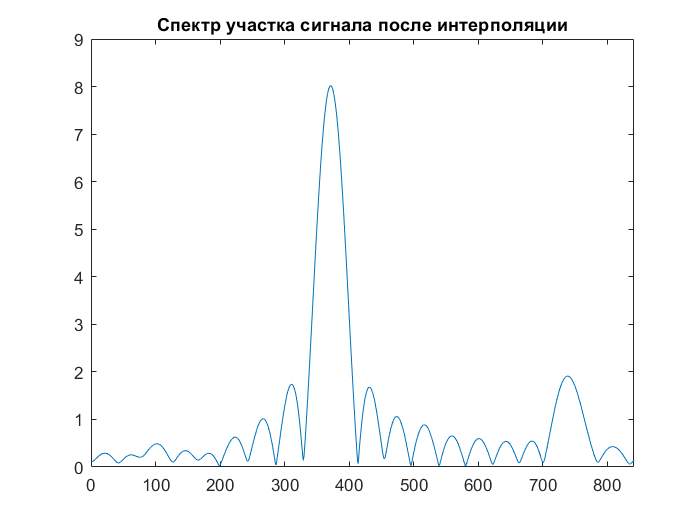

i = 1350;
S = z(i*Samples_num: (i+1)*Samples_num - 1);

k_interp = Fs/length(S) - 1;
zeros_num = floor( k_interp*Samples_num );
Zer = zeros(zeros_num, 1);
S2 = vertcat (Zer, S);

figure(4)
plot(abs(fft(S2)))
xlim([0 20] * k_interp)
title("Спектр участка сигнала после интерполяции")


Indexes = floor(L2 * Tab_F / Fs + 1);   % NOT FLAT!!!

Spec = abs(fft(S2));
Spec = Spec(1:L2/2);

M = Spec(Indexes);

Октава и нота. ранспонировки матрицы мы идем по октавам фиксируя ноты. С транспонировкой - фиксируется октава и мы идем по нотам. 

Значит индекс = октава*12 + нота

[Val, Ind] = max(M',[],[1 2], 'linear')   % Нахожу индекс максимума

Val = 8.0162

Ind = 31


note_num = mod(Ind, 12)            

note_num = 7

octave_num = (Ind - note_num)/12 + 1

octave_num = 3

## Определение нот композиции

Подготавливаем массив для нот композиции и задаем количество вырезок которые мы совершим

cuts = floor( length(z) / Samples_num ) - 1;    % Кол-во вірезок по времени
notes_lin = zeros(1, cuts);

Заготавливаем массив нулей для интерполяции

k_interp = Fs/Samples_num - 1;
zeros_num = floor( k_interp*Samples_num );
Zer = zeros(zeros_num, 1);

Заготавливаем массив индексов спектра для получаения амплитуд нот

Indexes = floor(L2 * Tab_F / Fs + 1);   % NOT FLAT!!!

Находим все ноты композиции и записываем в "notes_lin" в виде "нота*7 + октава". Такую форму дает линейная индексация от встроенной функции max.

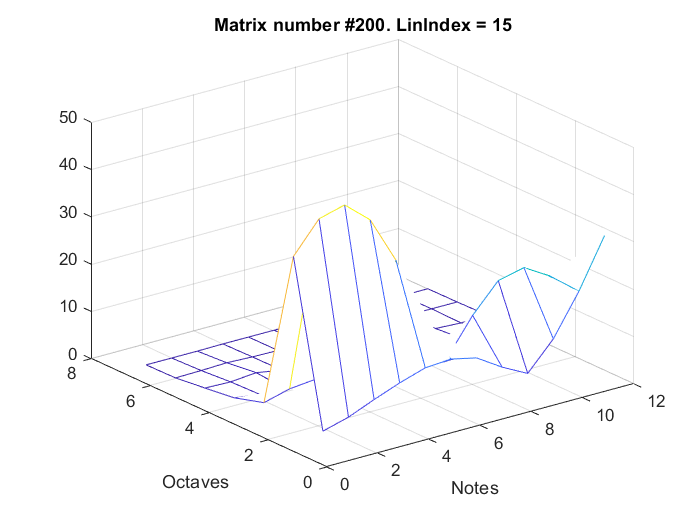

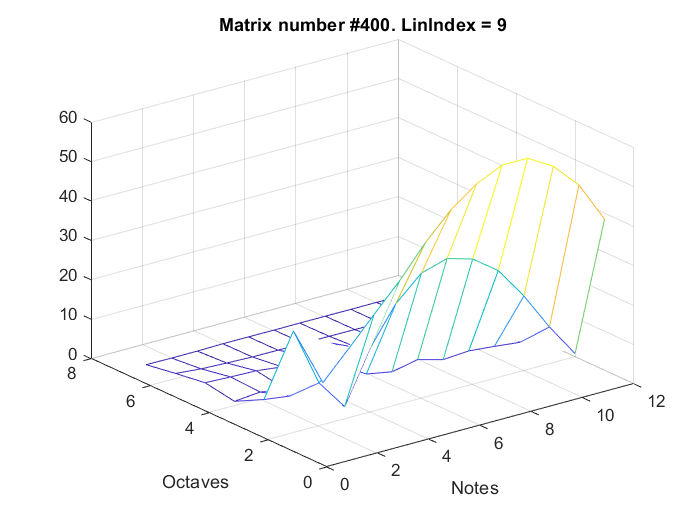

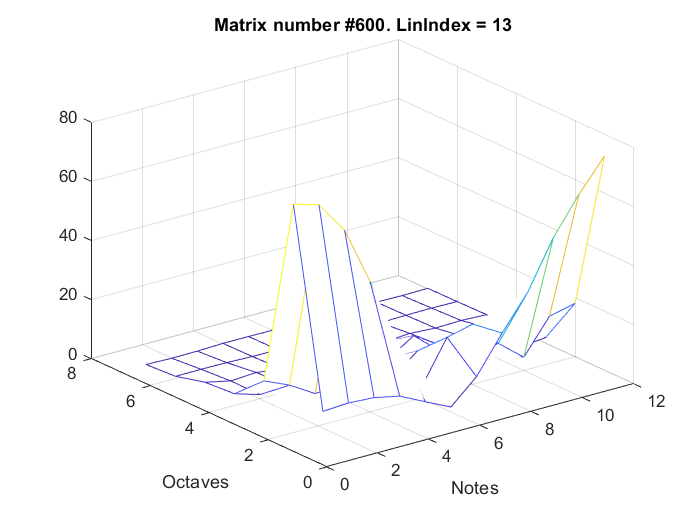

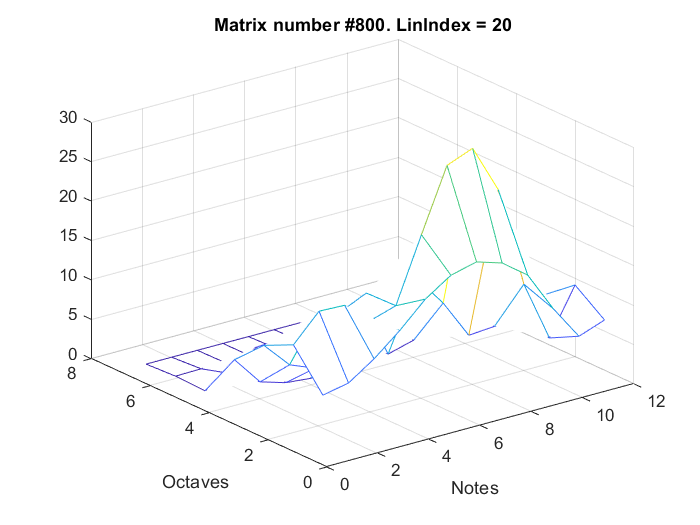

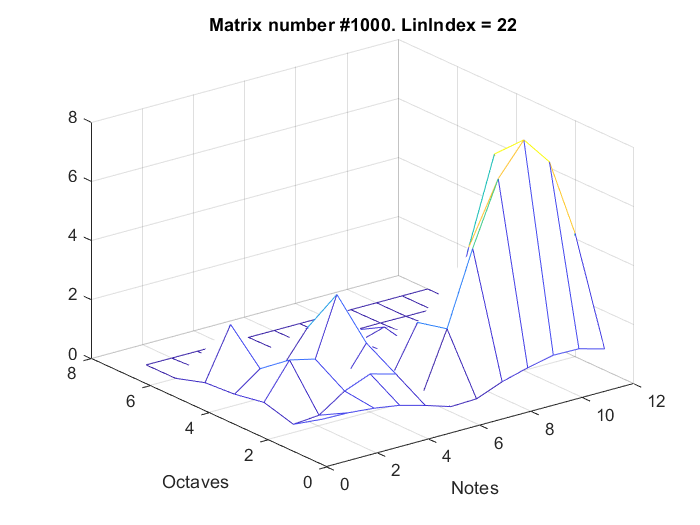

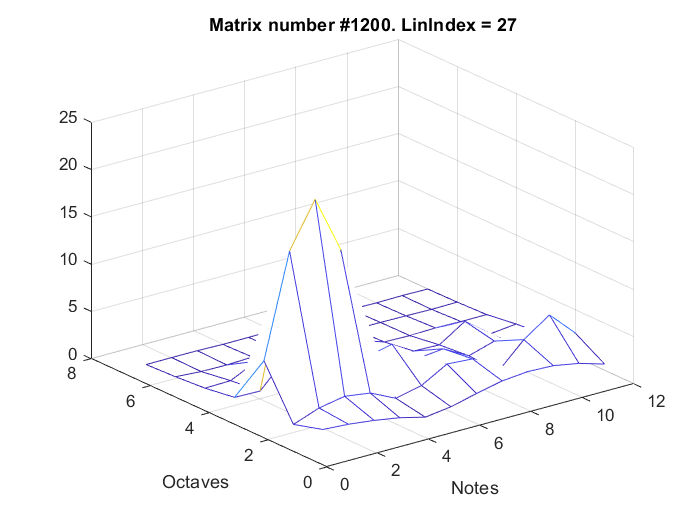

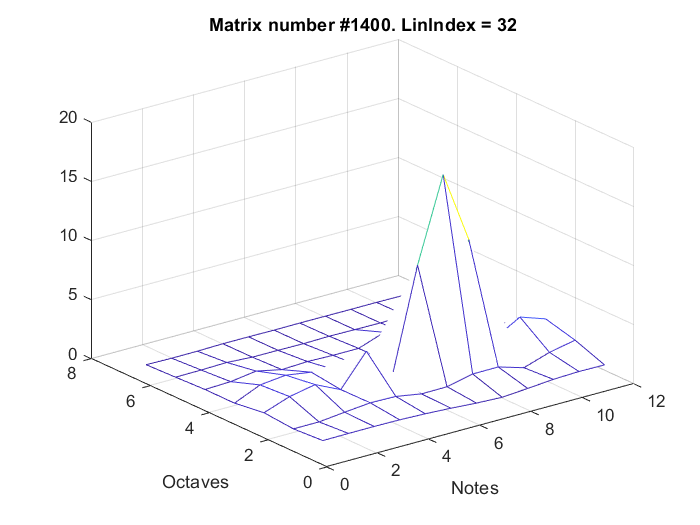

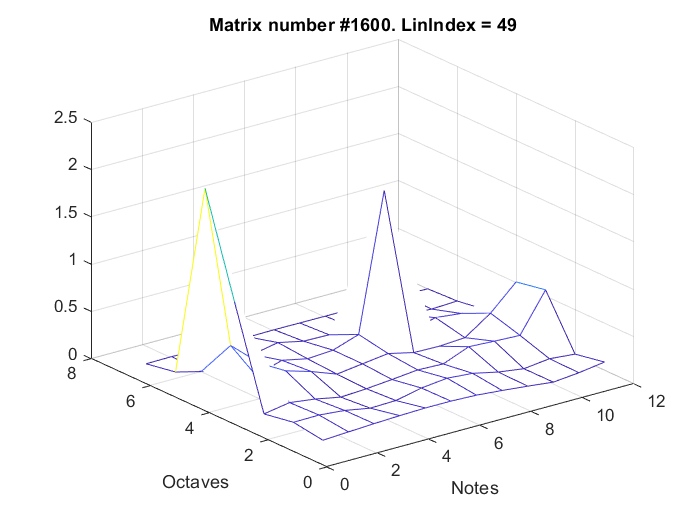

for i = 1:cuts
    
    n1 = i*Samples_num;         % Задаю пределы для вырезания участка сигнала
    n2 = (i+1)*Samples_num - 1;
    
    S = z(n1: n2);              % Берем участок сигнала
    S2 = vertcat (Zer, S);      % Интерполируем спектр
    Spec = abs(fft(S2));        % Находим спектр сигнала
    M = Spec(Indexes);          % Заполняем матрицу нот
    
    [Val, Ind] = max(M',[],[1 2], 'linear');   % Нахожу индекс максимума
    
    notes_lin(i) = Ind;         % Сохраняю текущую ноту
    
    if mod(i,200) == 0
        figure(i)
        mesh(M);
        xlabel("Notes")
        ylabel("Octaves")
        title("Matrix number #" + string(i) + ". LinIndex = " + string(Ind))
    end
    
end

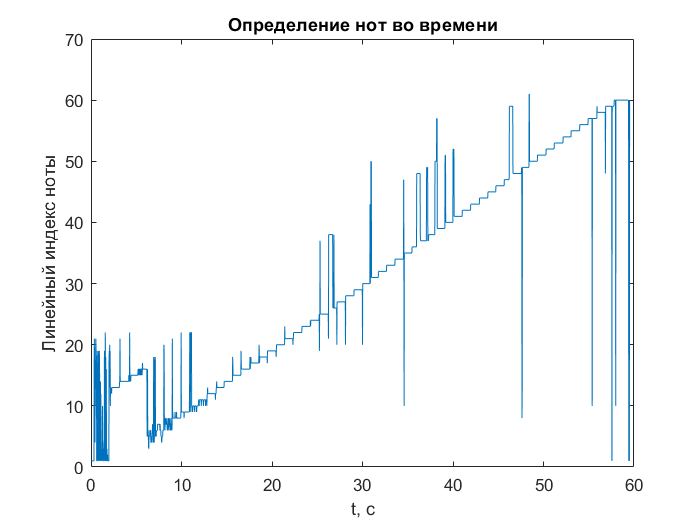


t = (1:cuts) * Samples_num / Fs;
plot(t, notes_lin)
xlabel("t, c")
ylabel("Линейный индекс ноты")
title("Определение нот во времени")

Определение нот реальной композиции

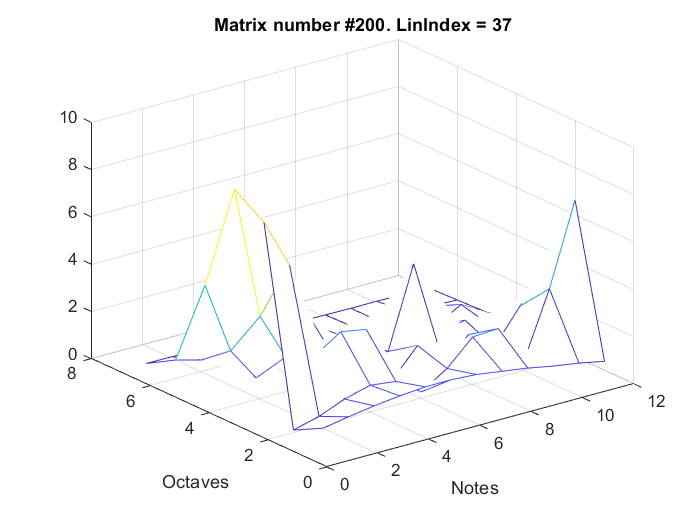

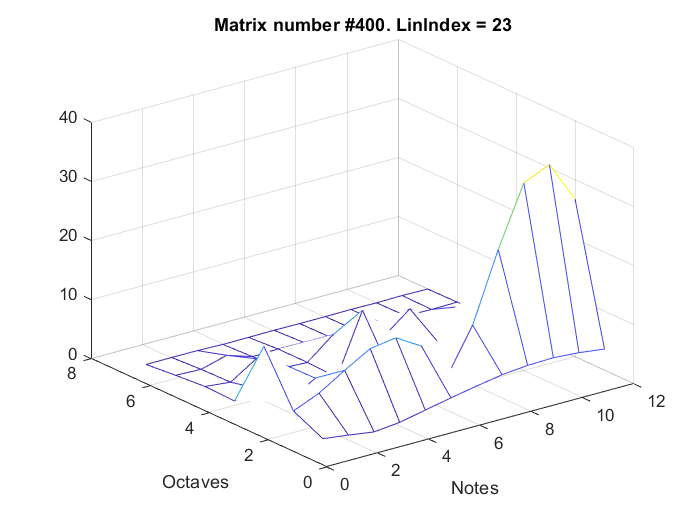

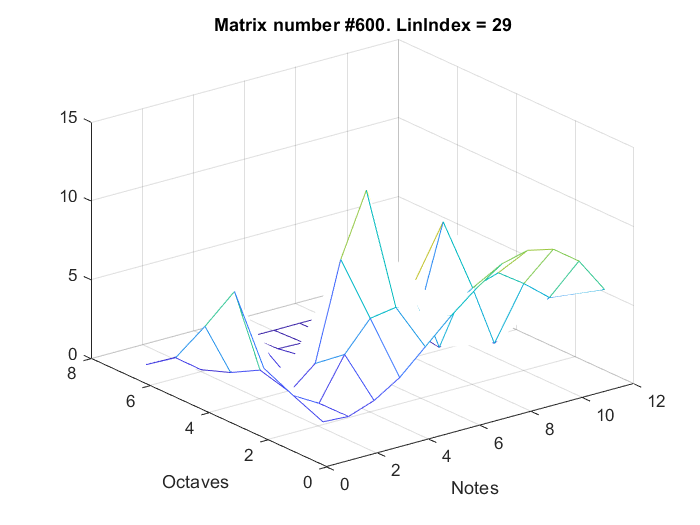

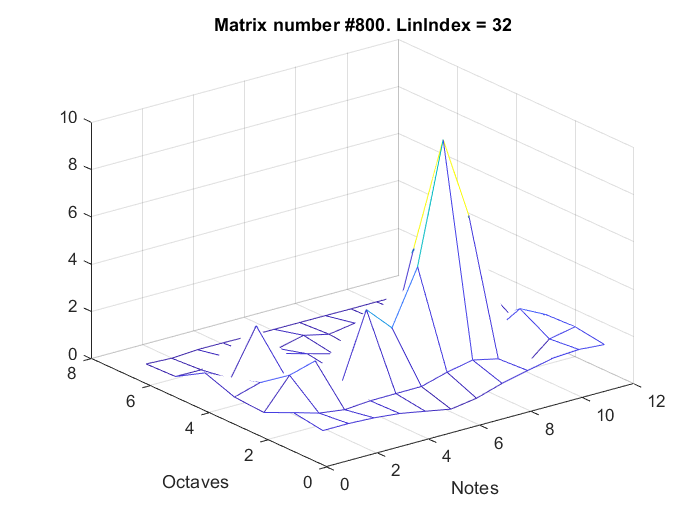

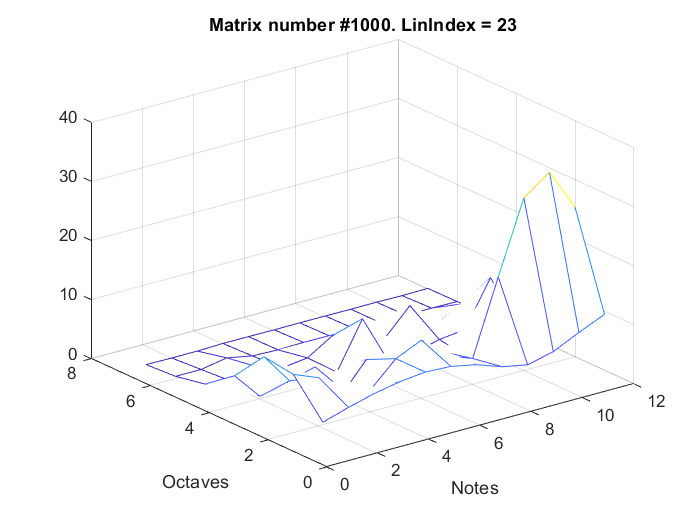

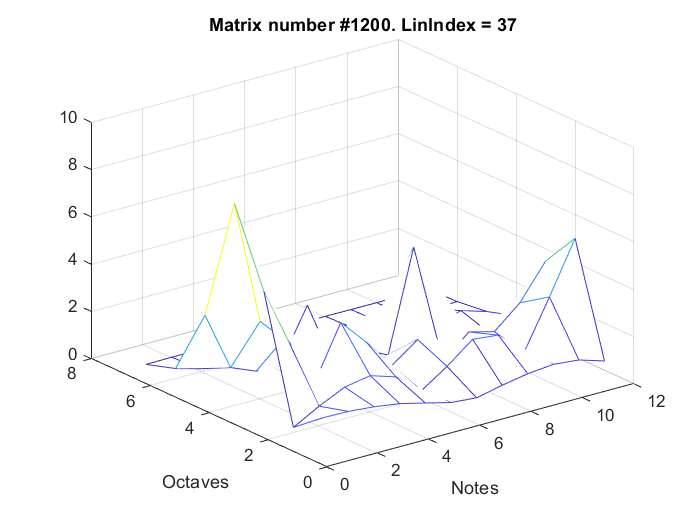

path = 'D:\Desktop\Studie\Diploma\Audio data\wav\Отрывок композиции для анализа-1.wav';
[y, Fs] = audioread(path);
z = y(:,1);

cuts = floor( length(z) / Samples_num ) - 1;    % Кол-во вірезок по времени
notes_lin = zeros(1, cuts);
k_interp = Fs/Samples_num - 1;
zeros_num = floor( k_interp*Samples_num );
Zer = zeros(zeros_num, 1);
Indexes = floor(L2 * Tab_F / Fs + 1);   % NOT FLAT!!!


for i = 1:cuts
    
    n1 = i*Samples_num;         % Задаю пределы для вырезания участка сигнала
    n2 = (i+1)*Samples_num - 1;
    
    S = z(n1: n2);              % Берем участок сигнала
    S2 = vertcat (Zer, S);      % Интерполируем спектр
    Spec = abs(fft(S2));        % Находим спектр сигнала
    M = Spec(Indexes);          % Заполняем матрицу нот
    
    [Val, Ind] = max(M',[],[1 2], 'linear');   % Нахожу индекс максимума
    
    notes_lin(i) = Ind;         % Сохраняю текущую ноту
    
    if mod(i,200) == 0
        figure(i+1)
        mesh(M);
        xlabel("Notes")
        ylabel("Octaves")
        title("Matrix number #" + string(i) + ". LinIndex = " + string(Ind))
    end
    
end


t = (1:cuts) * Samples_num / Fs

t =     0.0232    0.0464    0.0697    0.0929    0.1161    0.1393    0.1625    0.1858    0.2090    0.2322    0.2554    0.2786    0.3019    0.3251    0.3483    0.3715    0.3947    0.4180    0.4412    0.4644    0.4876    0.5108    0.5341    0.5573    0.5805    0.6037    0.6269    0.6502    0.6734    0.6966    0.7198    0.7430    0.7663    0.7895    0.8127    0.8359    0.8591    0.8824    0.9056    0.9288    0.9520    0.9752    0.9985    1.0217    1.0449    1.0681    1.0913    1.1146    1.1378    1.1610


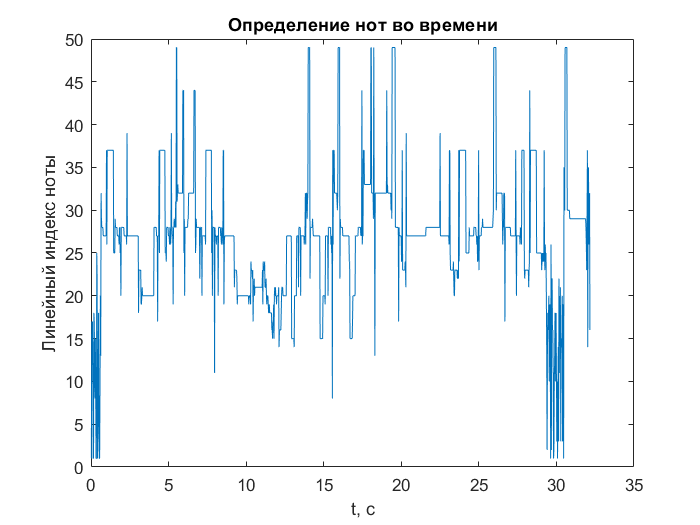

plot(t, notes_lin)
title("Определение нот во времени")
xlabel("t, c")
ylabel("Линейный индекс ноты")

Запись полученных нот в текстовый документ

Заготовленная таблица названий нот и октав

Tab_notes = ["C" "C#" "D" "D#" "E" "F" "F#" "G" "G#" "A" "A#" "B"];                  % 12
Tab_octaves = ["Большая" "Малая" "Первая" "Вторая" "Третья" "Четвертая" "Пятая"];    % 7
Tab_duration = ["4" "2" "1" "1/2" "1/4" "1/8" "1/16" "1/32"];                        % 8

Допустим мы получили линейный индекс 29. Знаем заранее что это 5 нота 3тей октавы или "Ми Первой октавы"

LinInd = [29 6];

note_num = mod(LinInd, 12)            

note_num =      5     6


octave_num = (LinInd - note_num)/12 + 1

octave_num =      3     1


note = Tab_notes(note_num)

note = 1×2 string array
    "E"    "F"


octave = Tab_octaves(octave_num)

octave = 1×2 string array
    "Первая"    "Большая"



duration = ["1/16" "1/4"]

duration = 1×2 string array
    "1/16"    "1/4"


Запись данных в текстовый файл

T = table(note, octave, duration, 'VariableNames', { 'note', 'octave', 'duration'} )

T = 1×3 table
       note              octave               duration    
    __________    _____________________    _______________

    "E"    "F"    "Первая"    "Большая"    "1/16"    "1/4"


writetable(T, 'MyFile.txt')

# НЕ ГОТОВО!!!

Пройдусь по всему сигналу, вырезая из него пачки по 1024 отчета. Из этих пачек я буду находить амплитуды каждой ноты, определять максимальную и говорить, что она является основным тоном. (Учитываем что играется только одна нота)

Делаю обезок длинной Samples_num. Использую перекрытие 1/2 по обрезкам тоже длинной Samples_num. Передаю спектр обрезка в функцию которая вынимает гармоники и находит максимум. Эта функция возвращает мне частоту с максимальной амплитудой. Я добавляю ее в конец массива. В итоге получаю массив который показывает в какое время какую ноту играли.

%{
cur_note = [0 0];
cuts = floor( length(z) / Samples_num ) - 1; % Количество вырезок из сигнала

for i = 1:cuts
    
    if (i > 1)
        L = Samples_num/2;
        S = z(i*Samples_num-L : (i+1)*Samples_num-L - 1);
        F = FillNoteMatrix(S);
        cur_note(end+1) = F;
    end
    
    S = z(i*Samples_num : (i+1)*Samples_num - 1);
    F = FillNoteMatrix(S);
    cur_note(end+1) = F;
    
end
%}

Определяю функцию которая будет избирать из спектра амплитуды, которые находяться по частотам нот и складывать их в M

Интерполяцией переведу спектр в такой, что бы шаг частоты был равен 1

%{

function F = FillNoteMatrix (S)
    k_interp = Fs/length(S) - 1;
    zeros_num = floor( k_interp*Samples_num);
    Zer = zeros(zeros_num, 1);
    S2 = vertcat (Zer, S);
    
    Spec = abs(fft(S2));        % Получаем спектр с шагом примерно 1Гц
    N = length(Spec);
    N2 = N/2;
    Spec = Spec(1:N2);
    
    for i = 1:length(M)
        
        index = floor( N * Tab_F(i) / Fs ); % Перевод частоты в индекс
        M(i) = Spec(index);
       
    end
    
    F; index = max(M);
    
end
%}